# Add cages to regular layout

This guide explains how to remove a "row" (or "column") of cages to a regular cage layout. The code works by remove cages according to a specified *side* of the farm. For simple (i.e. rectangular) cage layouts this means choosing one (or more) of the four orthogonal farm sides. For more complex cage layouts, alternative logic is required.

## Initialise a project and run

Let's just read in the project we have been using so far and seek to extend the cage layout.

projectDir = 'C:\newdepomod_projects\bay_of_fish';
project = Depomod.Project.create(projectDir);
run = project.solidsRuns.first;

A simple plot will remind us of our starting point

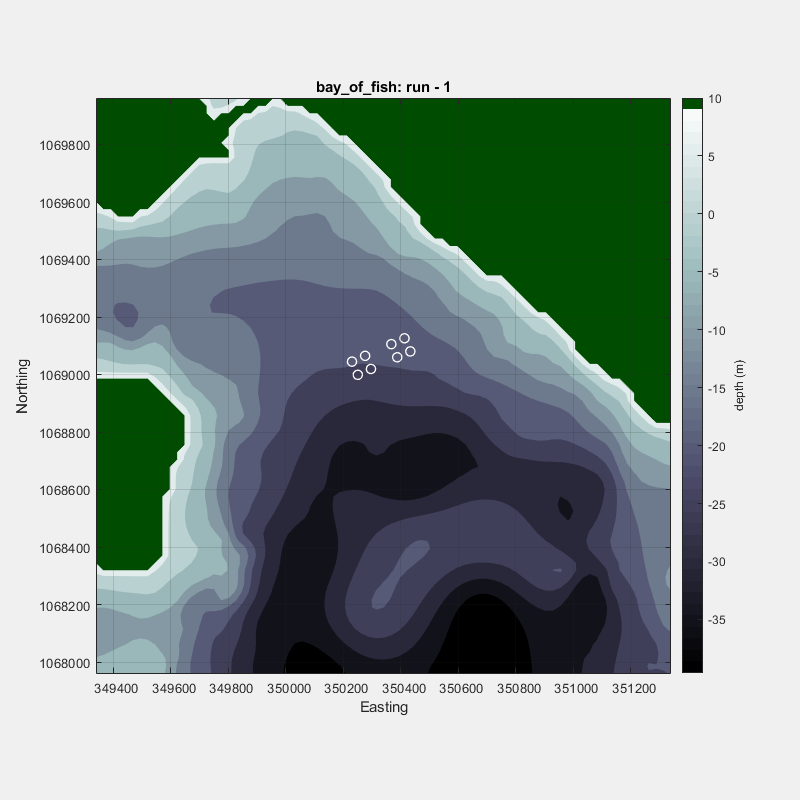

c =   ColorBar (depth (m)) with properties:

    Location: 'eastoutside'
      Limits: [-39.622682675 10]
    FontSize: 9
    Position: [0.852083333333351 0.158125000000073 0.0266666666666667 0.71875]
       Units: 'normalized'

  Show all properties

bool = logical
   1

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 -100 600 600]
       Units: 'points'

  Show all properties

run.plot('impact', 0)

We can also obtain the site layout representation in Matlab.

site = run.cages

site =   2 Site array with properties:

    cageGroups: {[4 Depomod.Layout.Cage.Group]  [4 Depomod.Layout.Cage.Group]}
          path: 'C:\newdepomod_projects\bay_of_fish\depomod\cages\bay_of_fish-1.depomodcagesxml'

## Identifying the required farm side

We can identify the individual sides of the site bounding box. This enables us to specify which row of column of cages to remove.

run.plot('impact',0);

c =   ColorBar (depth (m)) with properties:

    Location: 'eastoutside'
      Limits: [-39.622682675 10]
    FontSize: 9
    Position: [0.852083333333351 0.158125000000073 0.0266666666666667 0.71875]
       Units: 'normalized'

  Show all properties

bool = logical
   1

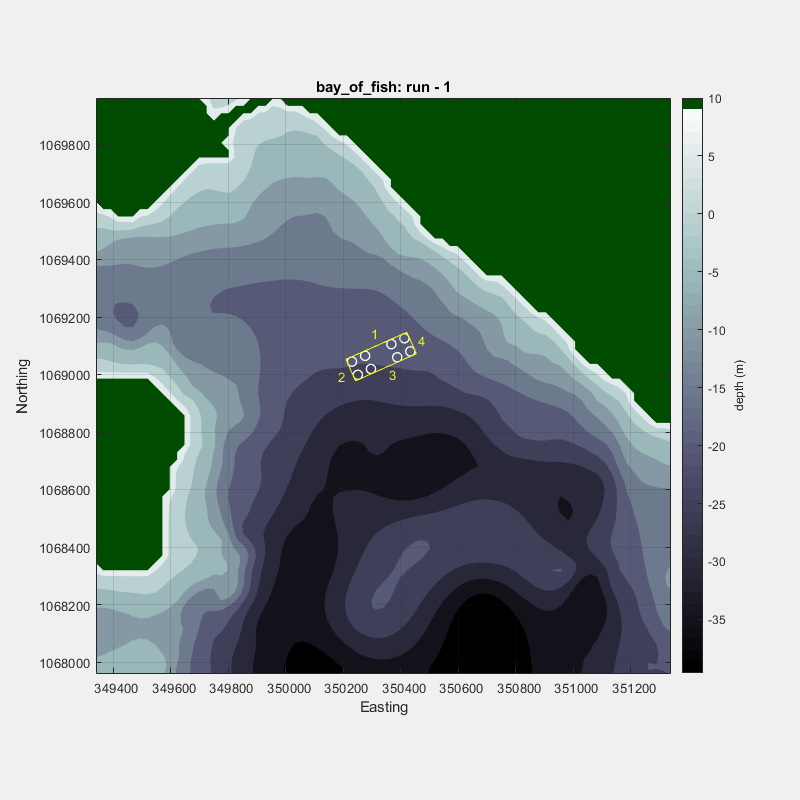

site.boundingBox.plotSides

## Removing cages along a specific side of a site

We can use some of the functionality of the toolbox to help us remove cages along a particular side of the farm. Suppose we decide we want to add cages along the southern edge of this farm, i.e. side #3. The following code gives a general pattern for achieving this.

side = 3;                % specify the required side along which to remove cages
site = run.cages;        % retrieve the run cages
site.consolidateCages;   % consolidate cage groups for simplicity

% identify the cages which fall along the side under consideration
[c,i]=site.boundingBox.Sides(side).cages;
idxs = find(i(:,3));

% delete the cages
site.cageGroups{1}.cages(idxs) = [];

% IMPORTANT - ensure all cages set to correct (uniformly distributed) proportion of discharge
for c = 1:site.sizeCages
    site.cageGroups{1}.cages{c}.proportion = 1/site.sizeCages;
end

% assign new cage layout to run object
run.cages = site;

Plot the new cages to check we have what we want

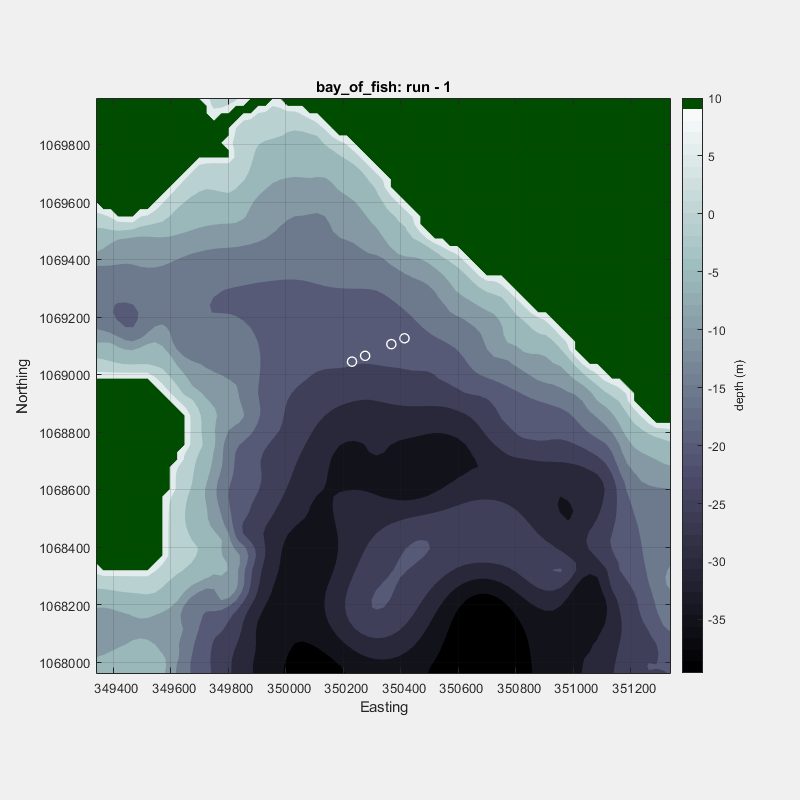

c =   ColorBar (depth (m)) with properties:

    Location: 'eastoutside'
      Limits: [-39.622682675 10]
    FontSize: 9
    Position: [0.852083333333351 0.158125000000073 0.0266666666666667 0.71875]
       Units: 'normalized'

  Show all properties

bool = logical
   1

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 -100 600 600]
       Units: 'points'

  Show all properties

run.plot('impact',0)

Okay, that seems fine. The same principle can be used to remove cages with respect to the other sides of the site. 

## Writing to file

As always, these changes have only been made with respect to the Matlab representation held in memory. To have effect in the model they need to be written back to file.

run.cages.toFile